# Two-Compartment Model

## 1. Load Dataset

clc, clearvars, close all

% load dataset (csv format) from repository folder: "MAT292_ODE_Project"
dataset = 'FINAL_mrgsolve_simulation';

% load data into matrix
Data = readmatrix(dataset);
row_n = size(Data, 1);

tf = 48; % set time domain

## 2. Test Plot (used only for sensitivity analysis)

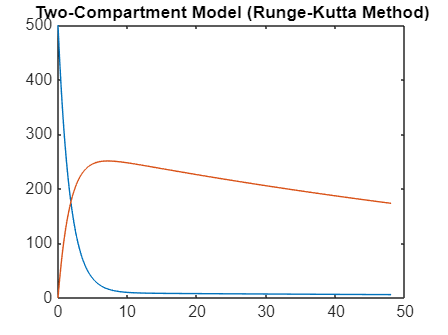

% paramaters with placeholder values
k10 = 0; % elimination rate
k12 = 1; % kinetic constant, central to peripheral
k21 = 0.01; % kinetic constant, peripheral to central
C0 = 500; % initial amount injected into central compartment

k_matrix = [0.1387 0.01 0.001; 0.1387 2.043 0.001; 0.1387 0.2043 0.01373; 0.4 0.2043 0.01373; 0.01 0.1057 0.001; 0.01 0.1057 0.01373; 0.2713 0.1057 0.01373; 0.2713 0.3 0.01373; 0.01 0.01 0.00727; 0.01 0.2043 0.00727; 0.2713 0.2043 0.00727; 0.2713 0.2043 0.02; 0.01 0.1057 0.00727; 0.2713 0.1057 0.00727; 0.2713 0.3 0.00727; 0.2713 0.3 0.02];
output = zeros(16,6);

% implementation of runge kutta method to solve ODE
h = 0.1; % h=timestep
ASol_RK = zeros(tf+1,3); % initialize matrix to store solution for two compartments

% set initial conditions
row = 16;
x=h; % x value incrementing by h
    ASol_RK = zeros(tf+1, 3);
    ASol_RK(1,1) = 0; % first column (time)
    ASol_RK(1,2) = C0; % second column (central compartment)
    ASol_RK(1,3) = 0; % third column (peripheral compartment)
    k10 = k_matrix(row, 1);
    k12 = k_matrix(row, 2);
    k21 = k_matrix(row, 3);
    for i = 1:tf/h
        ASol_RK(i+1, 1) = x; % set time
        x = x + h; % increment time
    
        % central compartment
        j1 = -k10 * ASol_RK(i, 2) - k12 * ASol_RK(i, 2) + k21 * ASol_RK(i, 3);
        j2 = -k10 * (ASol_RK(i, 2)+j1*h/2) - k12 * (ASol_RK(i, 2)+j1*h/2) + k21 * (ASol_RK(i, 3)+j1*h/2);
        j3 = -k10 * (ASol_RK(i, 2)+j2*h/2) - k12 * (ASol_RK(i, 2)+j2*h/2) + k21 * (ASol_RK(i, 3)+j2*h/2);
        j4 = -k10 * (ASol_RK(i, 2)+j3*h) - k12 * (ASol_RK(i, 2)+j3*h) + k21 * (ASol_RK(i, 3)+j3*h);
        ASol_RK(i+1, 2) = ASol_RK(i, 2) + h/6*(j1+2*j2+2*j3+j4);
    
        % peripheral compartment
        j1 = k12 * ASol_RK(i, 2) - k21 * ASol_RK(i, 3);
        j2 = k12 * (ASol_RK(i, 2)+j1*h/2) - k21 * (ASol_RK(i, 3)+j1*h/2);
        j3 = k12 * (ASol_RK(i, 2)+j2*h/2) - k21 * (ASol_RK(i, 3)+j2*h/2);
        j4 = k12 * (ASol_RK(i, 2)+j3*h) - k21 * (ASol_RK(i, 3)+j3*h);
        ASol_RK(i+1, 3) = ASol_RK(i, 3) + h/6*(j1+2*j2+2*j3+j4);
    
        %ASol_Euler(i+1, 2) = ASol_Euler(i, 2) + (-k10 * ASol_Euler(i, 2) - k12 * ASol_Euler(i, 2) + k21 * ASol_Euler(i, 3))*h;
        %ASol_Euler(i+1, 3) = ASol_Euler(i, 3) + (k12 * ASol_Euler(i, 2) -
        %k21 * ASol_Euler(i, 3))*h;
    
    end
ASol_RK(9, 2);
ASol_RK(41, 2);
ASol_RK(121, 2);
ASol_RK(9, 3);
ASol_RK(41, 3);
ASol_RK(121, 3);

% plot solutions calculated by runge kutta algorithm on the same graph
plot(ASol_RK(:,1), ASol_RK(:, 2))
hold on
plot(ASol_RK(:,1), ASol_RK(:, 3))
title("Two-Compartment Model (Runge-Kutta Method)")
hold off

## 3. Runge-Kutta Data Fitting and Errors

h = 0.1; % set increment
% Function for optimizing solution with Runge-Kutta according to parameters
function [MSE, RMSE, ASol_RK, RMSE_num1, RMSE_num2, MSE_real, RMSE_real, RMSE_num1_real, RMSE_num2_real] = calculateRungeKutta(k10, k12, k21, Data, C0, tf, h)
    
    ASol_RK = zeros(tf/h+1, 3); % initialize matrix of solutions

    % set initial conditions
    ASol_RK(1,1) = 0; % first column (time)
    ASol_RK(1,2) = C0; % second column (central compartment amount)
    ASol_RK(1,3) = 0; % third column (peripheral compartment amount)
    x=h; % x value incrementing by h
    for i = 1:tf/h
        ASol_RK(i+1, 1) = x; % set time
        x = x + h; % increment time

        % calculate central compartment
        j1 = -k10 * ASol_RK(i, 2) - k12 * ASol_RK(i, 2) + k21 * ASol_RK(i, 3);
        j2 = -k10 * (ASol_RK(i, 2) + j1*h/2) - k12 * (ASol_RK(i, 2) + j1*h/2) + k21 * (ASol_RK(i, 3)+j1*h/2);
        j3 = -k10 * (ASol_RK(i, 2) + j2*h/2) - k12 * (ASol_RK(i, 2) + j2*h/2) + k21 * (ASol_RK(i, 3)+j2*h/2);
        j4 = -k10 * (ASol_RK(i, 2)+j3*h) - k12 * (ASol_RK(i, 2)+j3*h) + k21 * (ASol_RK(i, 3)+j3*h);
        ASol_RK(i+1, 2) = ASol_RK(i, 2) + h/6*(j1+2*j2+2*j3+j4);

        % calculate peripheral compartment
        j1 = k12 * ASol_RK(i, 2) - k21 * ASol_RK(i, 3);
        j2 = k12 * (ASol_RK(i, 2)+j1*h/2) - k21 * (ASol_RK(i, 3)+j1*h/2);
        j3 = k12 * (ASol_RK(i, 2)+j2*h/2) - k21 * (ASol_RK(i, 3)+j2*h/2);
        j4 = k12 * (ASol_RK(i, 2)+j3*h) - k21 * (ASol_RK(i, 3)+j3*h);
        ASol_RK(i+1, 3) = ASol_RK(i, 3) + h/6*(j1+2*j2+2*j3+j4);
    end

    row_n = size(Data, 1);
    % calculate expected values for central compartment
    y1 = zeros(tf, 1);
    for n = 1:row_n
        %y1(n) = ASol_RK(fix(Data(n, 2)*(1/h)+1), 2); 
        y1(n) = ASol_RK(n, 2);
    end

    % calculate expected values for peripheral compartment
    y2 = zeros(tf, 1);
    for n = 1:row_n
        %y2(n) = ASol_RK(fix(Data(n, 2)*(1/h)+1), 3); 
        y2(n) = ASol_RK(n, 3);
    end

    % calculate MSE and RMSE, only first 80% of datapoints for training
    % initialize SSE for error calculations (central and peripheral compartment)
    RMSE_num1 = 0;
    RMSE_num2 = 0;

    % calculate SSE for central compartment
    for n = 1:round(0.8*(tf/h + 1))
        RMSE_num1 = RMSE_num1 + (abs(Data(n, 4)-y1(n)))^2;
        %RMSE_num1 = RMSE_num1 + (abs(Data(1 + (n-1)*h/inc, 4)-y1(n)))^2;
    end
    % calculate SSE for peripheral compartment
    for n = 1:round(0.8*(tf/h + 1))
        RMSE_num2 = RMSE_num2 + (abs(Data(n, 5)-y2(n)))^2;
    end
    
    % calculate MSE and RMSE for compartments
    MSE = (RMSE_num1 + RMSE_num2)/(2*round(0.8*(tf/h + 1)));
    RMSE = sqrt((RMSE_num1 + RMSE_num2)/(2*round(0.8*(tf/h + 1))));


    % calculate MSE and RMSE for unfitted data points (last 20%)
    RMSE_num1_real = 0;
    RMSE_num2_real = 0;

    % calculate SSE for central compartment
    for n = round(0.8*(tf/h + 1)) + 1:tf/h + 1
        RMSE_num1_real = RMSE_num1_real + (abs(Data(n, 4)-y1(n)))^2;
    end
    % calculate SSE for peripheral compartment
    for n = round(0.8*(tf/h + 1)) + 1:tf/h + 1
        RMSE_num2_real = RMSE_num2_real + (abs(Data(n, 5)-y2(n)))^2;
    end

    % calculate MSE and RMSE of test data for compartments
    MSE_real = (RMSE_num1_real + RMSE_num2_real)/(2*(tf/h + 1 - round(0.8*(tf/h + 1))));
    RMSE_real = sqrt((RMSE_num1_real + RMSE_num2_real)/(2*(tf/h + 1 - round(0.8*(tf/h + 1)))));
end


% data fitting based on experimental data
RMSE_min = Inf;

% set range of parameters being tested (fine-tuned based on results)
C0 = 500;
k10_t = linspace(0.01, 0.5, 20);
k12_t = linspace(0.01, 0.5, 20);
k21_t = linspace(0.004, 0.01, 30);

% loop through parameters, calling Runge-Kutta function each time
for k1 = k10_t 
    for k2 = k12_t
        for k3 = k21_t
            [MSE, RMSE, ASol_temp, RMSE_num1, RMSE_num2, MSE_real, RMSE_real, RMSE_num1_real, RMSE_num2_real] = calculateRungeKutta(k1, k2, k3, Data, C0, tf, h);
            if RMSE < RMSE_min
                RMSE_min = RMSE; % save minimum RMSE
                MSE_min = MSE;
                MSE_real_min = MSE_real;
                RMSE_real_min = RMSE_real;
                A1Sol_best = ASol_temp(:,2); % save central compartment solution
                A2Sol_best = ASol_temp(:,3); % save peripheral compartment solution

                % save parameters
                k10 = k1;
                k12 = k2;
                k21 = k3;
                
                % save SSE (both compartments)
                SSE = RMSE_num1_real + RMSE_num2_real;
            end
        end 
    end 
end 

% Parameter and Error Results
MSE_min % minimum MSE for training data

MSE_min = 6.0011

RMSE_min % minimum RMSE for training data

RMSE_min = 2.4497

MSE_real_min % MSE for test data

MSE_real_min = 4.6532

RMSE_real_min % RMSE for test data

RMSE_real_min = 2.1571

k10

k10 = 0.2679

k12

k12 = 0.1647

k21

k21 = 0.0052

SSE

SSE = 893.4103



% Akaike Information Criterion (AICc) and Bayesian Information Criterion (BIC) 
n = round(0.2*(tf/h + 1));
AICc = (2*n)*log(SSE/(2*n)) + 2*3 + 2*3*(3+1)/(2*n-3-1) + (2*n)*log(2*pi) + 2*n

AICc = 846.2098

BIC = (2*n)*log(SSE/2*n) + 3*log(2*n) + (2*n)*log(2*pi) + (2*n)

BIC = 2.6086e+03

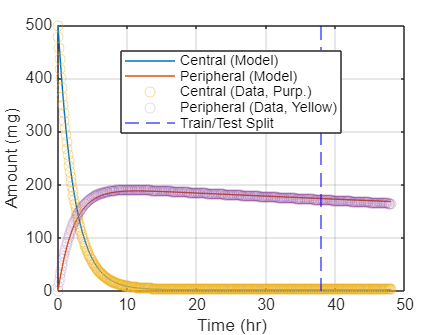



% Plot model fitted by Runge-Kutta
t = linspace(0, tf, tf/h+1);
plot(t, A1Sol_best) 
hold on
plot(t, A2Sol_best)
grid on
xlabel("Time (hr)")
ylabel("Amount (mg)")

% Plot experimental data on top of model
scatter(Data(:,2), Data(:,4), "MarkerEdgeAlpha", 0.5);
scatter(Data(:,2), Data(:,5), "MarkerEdgeAlpha", 0.2);
xline(round(0.8*tf), color = "blue", lineStyle = "--")
legend("Central (Model)","Peripheral (Model)", "Central (Data, Purp.)", "Peripheral (Data, Yellow)", "Train/Test Split", Location = "best");
hold off

## 4. Residuals of Fitted Plot

Residuals = zeros(tf+1,3);

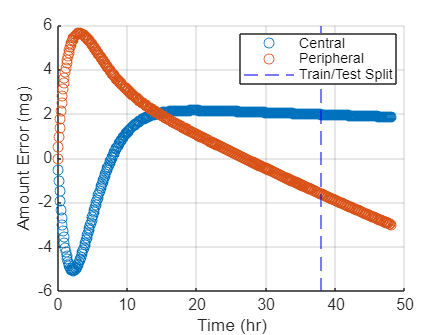

for i = 1:tf/h + 1
    %Residuals(i, 1) = Data(1 + (i-1)*h/inc, 2);
    Residuals(i, 1) = Data(i, 2);
    Residuals(i, 2) = Data(i, 4) - A1Sol_best(i);
    Residuals(i, 3) = Data(i, 5) - A2Sol_best(i);
end

% Plot Residuals of Two-Compartment Model
scatter(Residuals(:, 1), Residuals(:, 2))
hold on
grid on
scatter(Residuals(:, 1), Residuals(:, 3))
xline(round(0.8*tf), color = "blue", lineStyle = "--")
legend("Central", "Peripheral", "Train/Test Split", Location = "best")

xlabel("Time (hr)")
ylabel("Amount Error (mg)")